## **Abdullah Ahmed aa09303**

## **Lab 5**

**Task 1)**

Convolution is always commutative, meaning changing the order of the inputs does not affect the result. When both signals, u and v, are rectangular pulses, the output w forms a triangular pulse. If u is a triangular pulse and v is a rectangular pulse, the resulting output takes the shape of a downward-facing parabola. Similarly, when u is rectangular and v is triangular, the output remains a downward-facing parabola.

**Task 2)**

If both input sequences, u and v, have the same length L, the convolution output will have a length of 2L - 1. This is found by summing the lengths of the inputs and subtracting one. When the input sequences have different lengths, M and N, the length of the convolution output is given by M + N - 1.

**Task 3)**

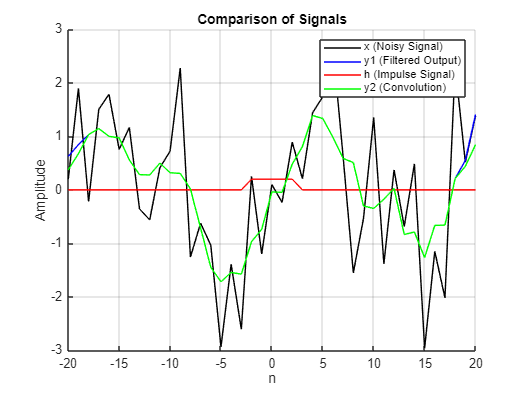

clc;
clear;
close all;
n = -20:1:20;
noise = randn(size(n));
x_n = sin(0.3142 * n) + noise;
y1 = movmean(x_n, 5);

impulse = n == 0;
h_n = movmean(impulse, 5);
y2 = conv(x_n, h_n, "same");

figure;
hold on;
plot(n, x_n, 'k');    
plot(n, y1, 'b');            
plot(n, h_n, 'r');            
plot(n, y2, 'g');            
hold off;
xlabel('n');
ylabel('Amplitude');
title('Comparison of Signals');
legend('x (Noisy Signal)', 'y1 (Filtered Output)', 'h (Impulse Signal)', 'y2 (Convolution)');
grid on;

**Task 4)**

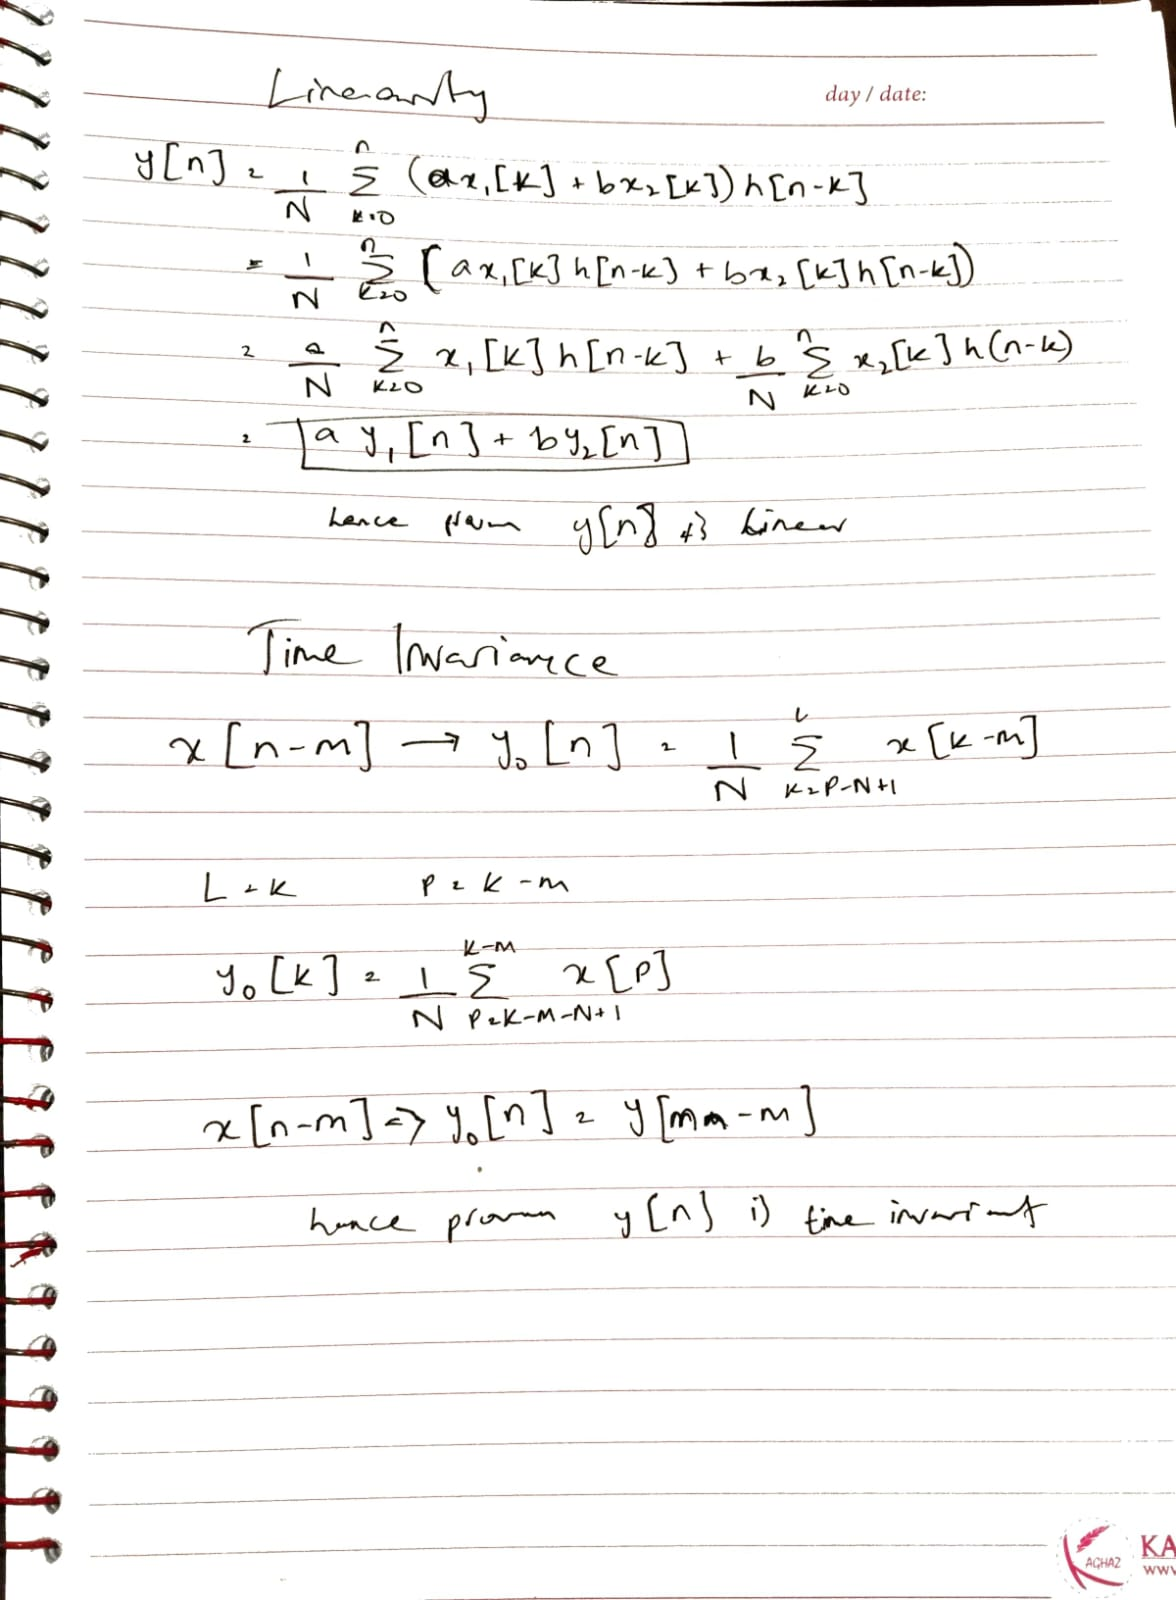

**Task 5)**

clc;
clear;
close all;
[impulseResponse, sampleRateIR] = audioread("1st_baptist_nashville_balcony.wav");
disp(size(impulseResponse));

      288000           2




% Play the impulse response
soundsc(impulseResponse, sampleRateIR);
pause(length(impulseResponse) / sampleRateIR);

[inputSignal, sampleRateInput] = audioread("ringtone.wav");
disp(size(inputSignal));

      111616           1



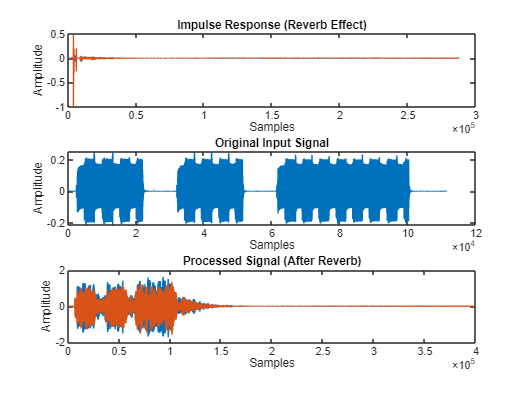


% Play the input signal
soundsc(inputSignal, sampleRateInput);
pause(length(inputSignal) / sampleRateInput);

% left and right channels
leftIR = impulseResponse(:, 1);
rightIR = impulseResponse(:, 2);

% Apply convolution
outputLeft = conv(inputSignal, leftIR);
outputRight = conv(inputSignal, rightIR);

% Combine processed signals
processedSignal = [outputLeft, outputRight];

% Play the reverb audio
soundsc(processedSignal, sampleRateInput);

figure;
subplot(3, 1, 1);
plot(impulseResponse);
title('Impulse Response (Reverb Effect)');
xlabel('Samples');
ylabel('Amplitude');

subplot(3, 1, 2);
plot(inputSignal);
title('Original Input Signal');
xlabel('Samples');
ylabel('Amplitude');

subplot(3, 1, 3);
plot(processedSignal);
title('Processed Signal (After Reverb)');
xlabel('Samples');
ylabel('Amplitude');

**POSTLAB**

**Task 6)**

clc;
clear;
close all;
function w = discrete_convo(u, v)
    % Initialize output vector
    % Length of convolution is length(u) + length(v) - 1
    w = zeros(1, length(u) + length(v) - 1);
    
    % Implement convolution sum
    for n = 1:length(w)
        for k = 1:length(v)
            % Check if the index is within bounds of u
            if (n-k+1 >= 1) && (n-k+1 <= length(u))
                w(n) = w(n) + u(n-k+1) * v(k);
            end
        end
    end
end

testing function:

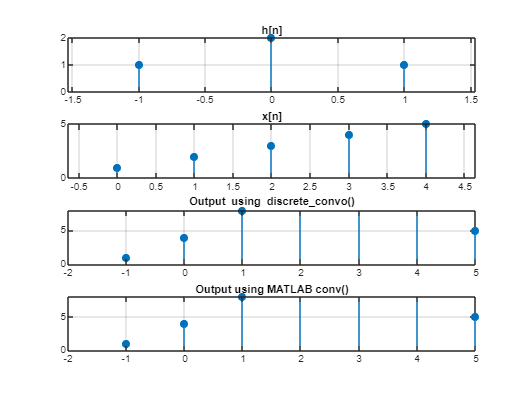

h = [1, 2, 1]; 
x = [1, 2, 3, 4, 5]; 

w1 = discrete_convo(x, h);
w2 = conv(x, h);

% Create time vectors for plotting
n_h = -1:1;  % Time vector for h[n]
n_x = 0:4;   % Time vector for x[n]
n_w = -1:5;  % Time vector for output

figure;
subplot(4,1,1);
axis([-2 5 0 8]);
stem(n_h, h, 'filled');
title('h[n]');
grid on;

subplot(4,1,2);
axis([-2 5 0 8]);
stem(n_x, x, 'filled');
title('x[n]');
grid on;

subplot(4,1,3);
stem(n_w, w1, 'filled');
axis([-2 5 0 8]);
title('Output using discrete\_convo()');
grid on;

subplot(4,1,4);
stem(n_w, w2, 'filled');
axis([-2 5 0 8]);
title('Output using MATLAB conv()');
grid on;